% load in gombertz growth data
T = readtable('gombertz_growth_data_1000_points.csv');
days_pred = table2array(T(1,:));
gombertz = table2array(T(2,:));
logistic = table2array(T(3,:));

% load in population change data 1st Jan Weaning
T0101 = readtable('Weaned1janPopChange.csv', 'VariableNamingRule',"preserve");
date_of_change0101 = table2array(T0101(:,1));
days_axis0101 = datetime(date_of_change0101)

pop_change0101 = cumsum(table2array(T0101(:,2))); %takes total sum of all prev terms

% load in population change data 5th Feb Weaning
T0502 = readtable('Weaned5febPopChange.csv', 'VariableNamingRule',"preserve");
date_of_change0502 = table2array(T0502(:,1));
days_axis0502 = datetime(date_of_change0502)
pop_change0502 = cumsum(table2array(T0502(:,2))); %takes total sum of all prev terms

% set up x axis in days
% start_date = datetime(2019,12,1);
% end_date = datetime(2020,6,15);
% days_axis = start_date:end_date;

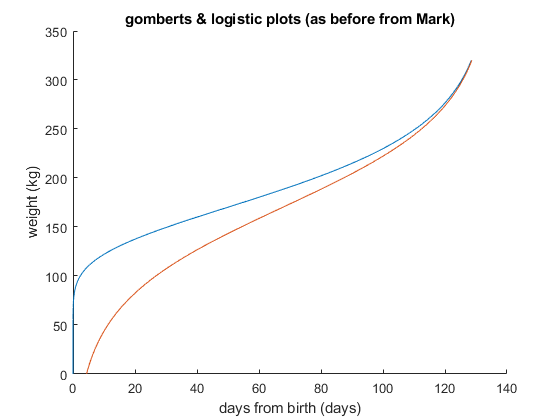

% plot weight against time
hold on
plot(gombertz, days);
plot(logistic, days);
title('gomberts & logistic plots (as before from Mark)')
xlabel('days from birth (days)')
ylabel('weight (kg)')

% load in population change in time
% plot days against weight, days against population

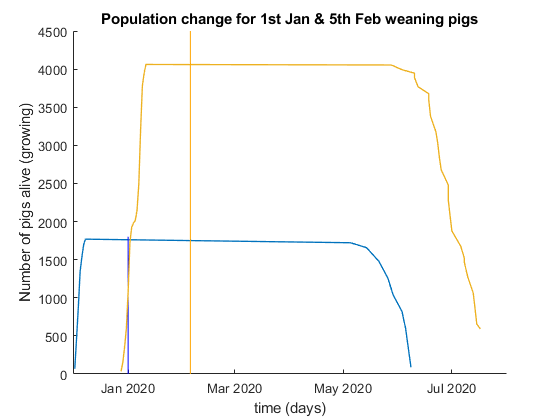

% plot population against time
clf
hold on
plot(days_axis0101, pop_change0101, 'LineWidth', 1)
plot([datetime(2020,1,1) datetime(2020,1,1)], ylim, "Color",'blue');
plot(days_axis0502, pop_change0502, "LineWidth", 1)
plot([datetime(2020,2,5) datetime(2020,2,5)], ylim, "Color",'#FFA500');
title('Population change for 1st Jan & 5th Feb weaning pigs')
xlabel('time (days)')
ylabel('Number of pigs alive (growing)')